# MATLAB Onramp Deploy

## Problem 1

You have been provided with 3 .csv files containing the races results for 3 years of Formula 1. Your job is to upload these files into the same folder as this MATLAB lives script, so that you can analyze the data. Once you can access the files, extract data from them to find out which driver won the most races each year. Make sure that your code prints out the statement that states who won the most races. For example: "Driver No. 77 won the most races (11 wins) in 2019".

*Hint: Refer to Part 2 of the development assignment to get an idea of how to approach this activity and use the column containing the driver number to figure out who won the most races.* 

% Setup the MATLAB environment by clearing the command window and workspace
clc; clear;

% Load the data from the 2019 file and store it in a variable called
% Race2019. Make a variable for each year.
Race2019 = readtable("2019F1Results.csv");
Race2016 = readtable("2016F1Results.csv");
Race2012 = readtable("2012F1Results.csv");

% Extract data from the appropriate column of Race2019 to find out who won the most
% races. Store the extracted column in a variable called Winner2019. Make a
% variable for each year. 
Winner2019 = Race2019.DriverNumber;
Winner2016 = Race2016.DriverNumber;
Winner2012 = Race2012.DriverNumber;

% The mode function shows who won the most races and how many wins they
% got. Store the outputs of the mode functions in the variables
% MostWins2019 and Wins2019. Repeat the same process for each year. 
[MostWins2019, Wins2019] = mode(Winner2019);
[MostWins2016, Wins2016] = mode(Winner2016);
[MostWins2012, Wins2012] = mode(Winner2012);


% Print a statement that shows who won the most races and how many races
% they won for each year.
fprintf("Driver No. %d won the most races (%d wins) in 2019.", MostWins2019, Wins2019);

Driver No. 44 won the most races (11 wins) in 2019.

fprintf("Driver No. %d won the most races (%d wins) in 2016.", MostWins2016, Wins2016);

Driver No. 44 won the most races (10 wins) in 2016.

fprintf("Driver No. %d won the most races (%d wins) in 2012.", MostWins2012, Wins2012);

Driver No. 1 won the most races (5 wins) in 2012.

**If you wanted to know what races were won by the driver that won the most races in 2019 you could use the lines of code below:**

% Identifies the rows where the variables Winner2019 and MostWins2019
% contain the same driver number. Excludes the columns output since that
% information is irrelevant. 
[row_indices, ~] = find(Winner2019 == MostWins2019);

% Extracts the names of each Grand Prix and stores it in a non-numerical
% column array.
GP =  categorical(Race2019.GrandPrix);

% Stores the names of the Grand Prix corresponding to the row indices identified in line 33.
Names = GP(row_indices);

% Displays which races were won by the 2019 Champion
disp(Names)

     Bahrain 
     China 
     Spain 
     Monaco 
     Canada 
     France 
     Great Britain 
     Hungary 
     Russia 
     Mexico 
     Abu Dhabi 



B) You been provided 3 files showing which driver set the fastest lap each race for the 2012, 2016, and 2019 seasons. Write a code that can find out which driver got the fastest lap awards and show where they had their fastest laps. 

*Hint: Use a code similar to part 1. *

% Call data from the file
Laps2016 = readtable("2016FastestLap.csv");

% Find who was the fastest and how many fast laps they had
[Fastest2016, nLaps] = mode(Laps2016.DriverNumber);

% Print a statement
fprintf("Driver No. %d had the most fastest laps (%d Laps) in 2016.", Fastest2016, nLaps);

Driver No. 6 had the most fastest laps (6 Laps) in 2016.

% Find which rows of Fastest2016 and the DriverNumber column in the table
% Laps2016 have the same driver number.
[row_index, ~] = find(Fastest2016 == Laps2016.DriverNumber);

% Make an array with the race names
Race = categorical(Laps2016.GrandPrix);

% Displays the names of the Grand Prix where the specific driver set the
% fastest lap
Race = Race(row_index);
disp(Race);

     Bahrain 
     Russia 
     Canada 
     Europe 
     Great Britain 
     Malaysia 



## Problem 2

A) Continue to use the .csv file containing the race results for 2019 from Problem 1  and present the race winner results in the form of piechart. Mark sure to add an appropriate title to your plot.

*Hint: Use the first 2 examples in MATLAB documentation to learn how to create a Pie chart . Should only require about 4 lines of code. *

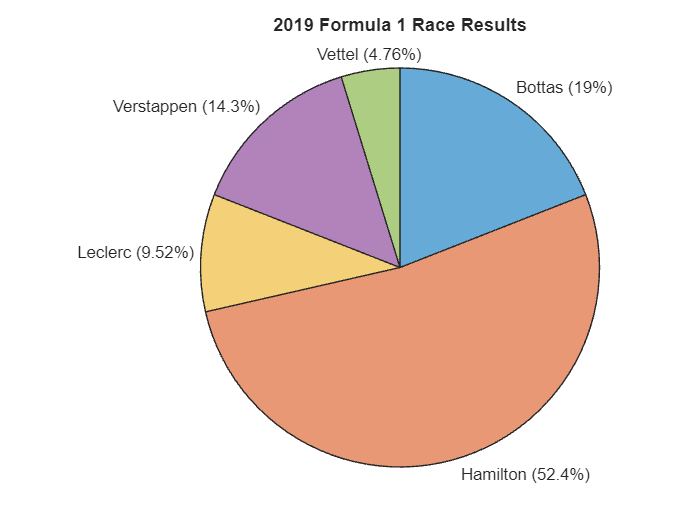

% Extract the Driver column from the table containing the 2019 race
% results. In this case, we stored that data in the variable Race2019
RaceWinners = Race2019.Driver;

% Use the categorical() function to create a categorical array that 
% efficiently stores non-numeric data. 
RaceWinners = categorical(RaceWinners);

% A common use of categorical arrays is to specify groups of rows in a
% table. In this case, we will use it to make a pie chart.
piechart(RaceWinners)

% Adds a title to the piechart
title("2019 Formula 1 Race Results")

B) Write code that a Formula 1 team could use to only analyze the races from the first half of the season. Based on this data who would be the expected winner each year. Make sure your code prints out a statement with the expected winner. 

*Hint: Recall the syntax used in the development activities to extract data from only the desired rows.*

% Load the data from the file and store in a variable
Race2019 = readtable("2019F1Results.csv");

% Extract the column containing the number of the race winners
Wins = Race2019.DriverNumber;

% Find the number of rows in the column to know the number of races
[rows, ~] = size(Wins);

% Divide the number of rows by 2 to cut the season in half, since the
% number can be odd, we should "round" to make sure we have an integer
rows = round(rows/2);

% Create a variable containing data for only half of the season
HalfSeason = Wins(1:rows, 1);

% Find who won the most races in the first half of the season
HalfWinner = mode(HalfSeason);
fprintf("Driver No. %d is the expected winner in 2019!", HalfWinner);

Driver No. 44 is the expected winner in 2019!